## Classification with Machine Learning

Classification is the problem of identifying which set of categories based on observation features. The decision is based on a training set of data containing observations where category membership is known (supervised learning) or where category membership is unknown (unsupervised learning). A basic example is to determine the number from pixelated images in a built-in sklearn dataset. The script predicts 0-9 from the following images with a Support Vector Classifier.

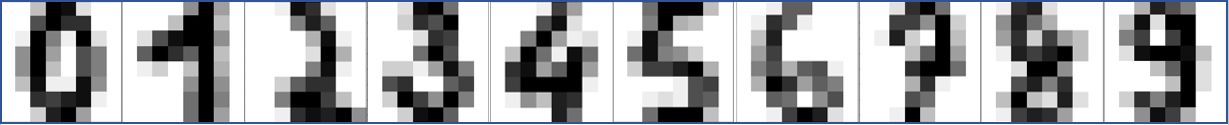

In this case, the 8x8 (64) pixels are the input features to the classifier. The output of the classifier is a number from 0 to 9. The classifier is trained on 898 images and tested on the other 50% of the data. This is an example of supervised learning where the data is labeled with the correct number. An unsupervised learning method would not have the number labels on the training set. An unsupervised learning method creates categories instead of using labels.

The first step in classification is to curate the data. This typically involves enumeratation, scaling, outlier detection, and splitting the data into training, test, and an optional validation set. One way to learn about classification methods is through concrete examples where the results are visualized as 2D data. The homogeneous data needs data labels (True/False) because there is no segregation of the data that is required for unsupervised learning methods.

**Homogeneous Population: 0=Linear, 1=Quadratic, 2=Target**

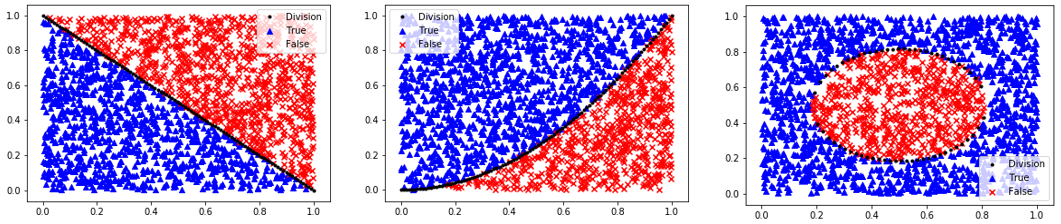

**Segregated Clusters: 3=Moons, 4=Concentric Circles, 5=Distinct Clusters**

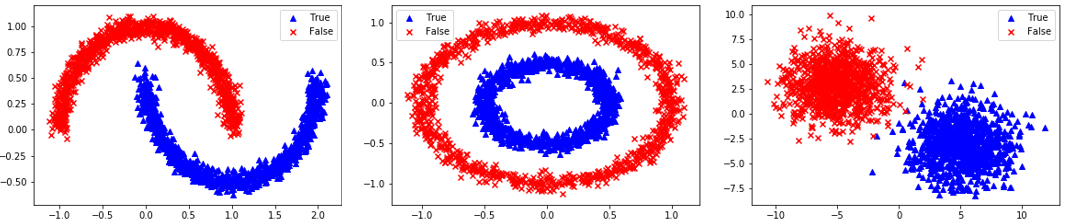

For each of the supervised and unsupervised machine learning methods, the strengths and weaknesses are detailed. The more popular methods are reviewed although there are many new methods that are developed each year. The same principles of training, testing, and deployment are common to most learning methods.

## Classification with Supervised Learning

### **Logistic Regression**

**Definition:** Logistic regression is a machine learning algorithm for classification. In this algorithm, the probabilities describing the possible outcomes of a single trial are modelled using a logistic function.

**Advantages:** Logistic regression is designed for this purpose (classification), and is most useful for understanding the influence of several independent variables on a single outcome variable.

**Disadvantages:** Assumes all predictors are independent of each other, and assumes data is free of missing values.

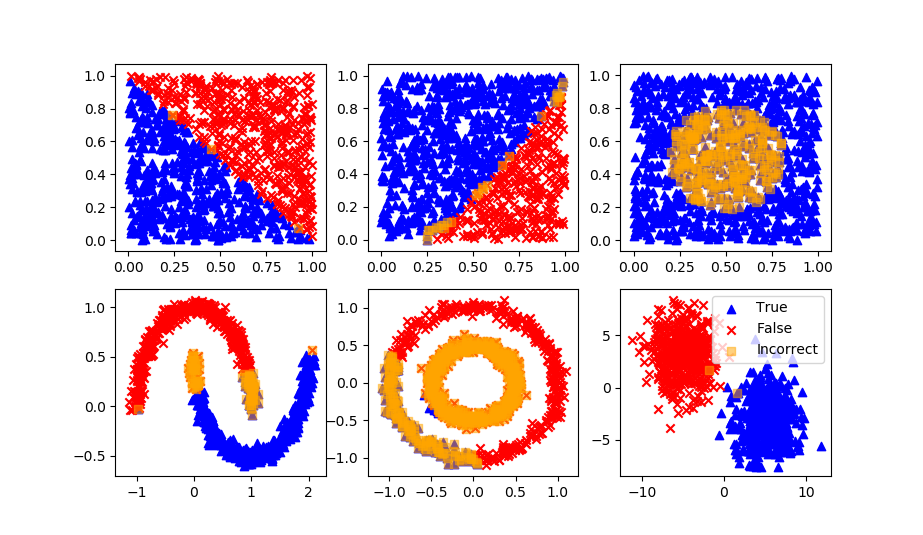

### Naïve Bayes

**Definition:** Naive Bayes algorithm based on Bayes’ theorem with the assumption of independence between every pair of features. Naive Bayes classifiers work well in many real-world situations such as document classification and spam filtering.

**Advantages:** This algorithm requires a small amount of training data to estimate the necessary parameters. Naive Bayes classifiers are extremely fast compared to more sophisticated methods.

**Disadvantages:** Naive Bayes is is known to be a bad estimator.

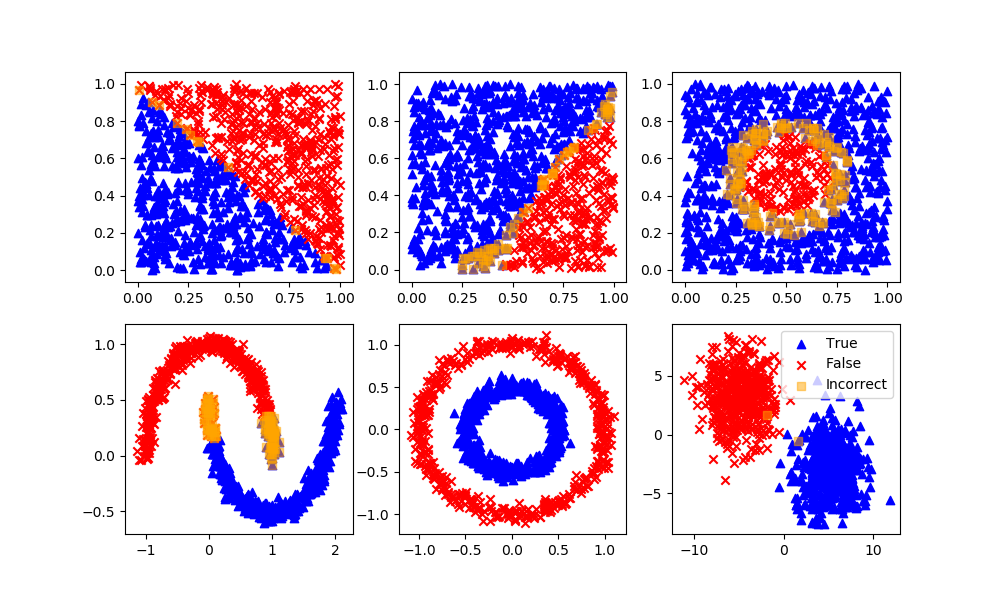

### Stochastic Gradient Descent

**Definition:** Stochastic gradient descent is a simple and very efficient approach to fit linear models. It is particularly useful when the number of samples is very large. It supports different loss functions and penalties for classification.

**Advantages:** Efficiency and ease of implementation.

**Disadvantages:** Requires a number of hyper-parameters and it is sensitive to feature scaling.

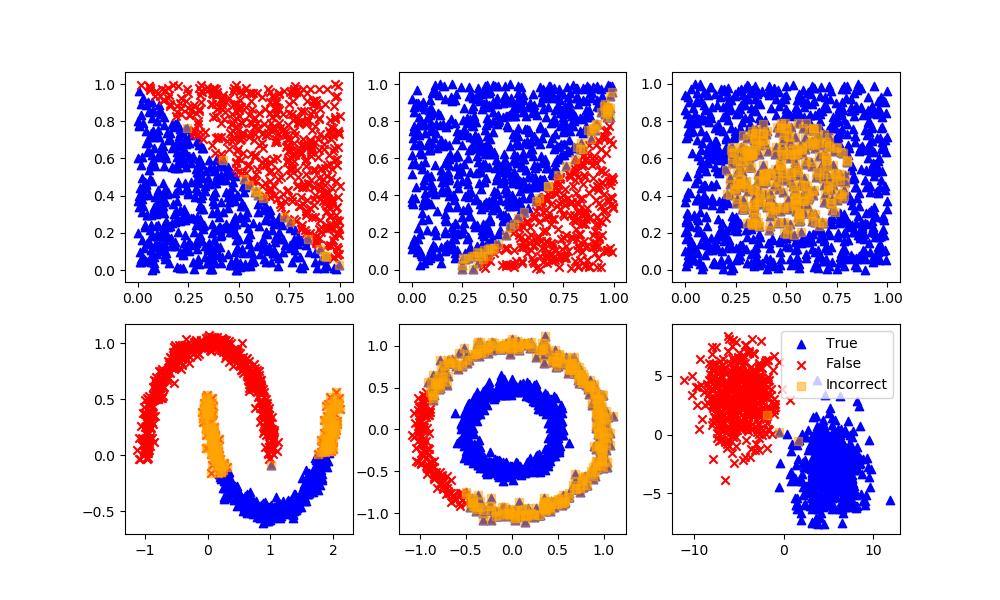

### K-Nearest Neighbors

**Definition:** Neighbors based classification is a type of lazy learning as it does not attempt to construct a general internal model, but simply stores instances of the training data. Classification is computed from a simple majority vote of the k nearest neighbors of each point.

**Advantages:** This algorithm is simple to implement, robust to noisy training data, and effective if training data is large.

**Disadvantages:** Need to determine the value of K and the computation cost is high as it needs to computer the distance of each instance to all the training samples. A feedback loop can be added to determine the number of neighbors.

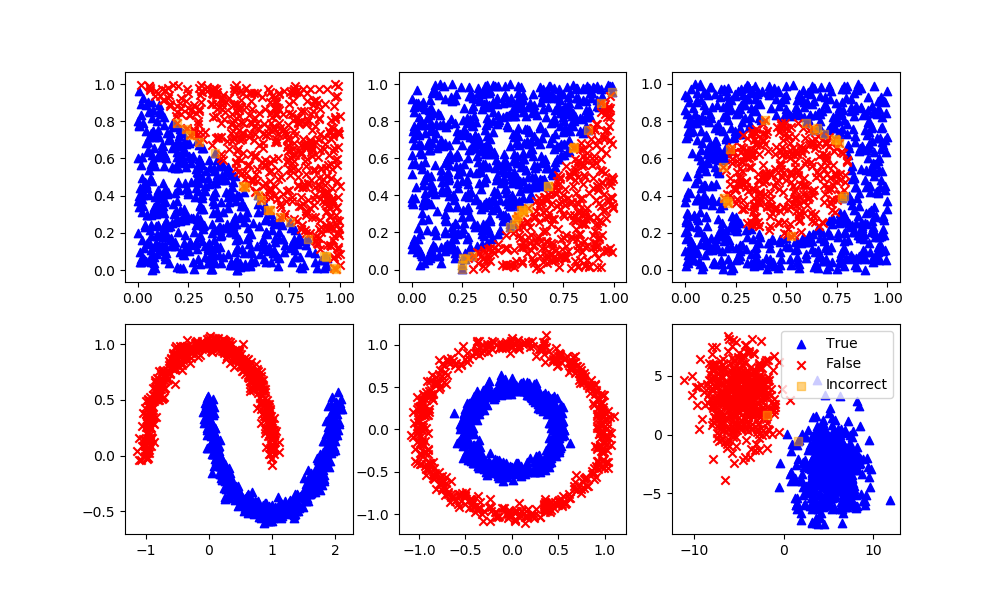

### Decision Tree

**Definition:** Given a data of attributes together with its classes, a decision tree produces a sequence of rules that can be used to classify the data.

**Advantages:** Decision Tree is simple to understand and visualise, requires little data preparation, and can handle both numerical and categorical data.

**Disadvantages:** Decision tree can create complex trees that do not generalise well, and decision trees can be unstable because small variations in the data might result in a completely different tree being generated.

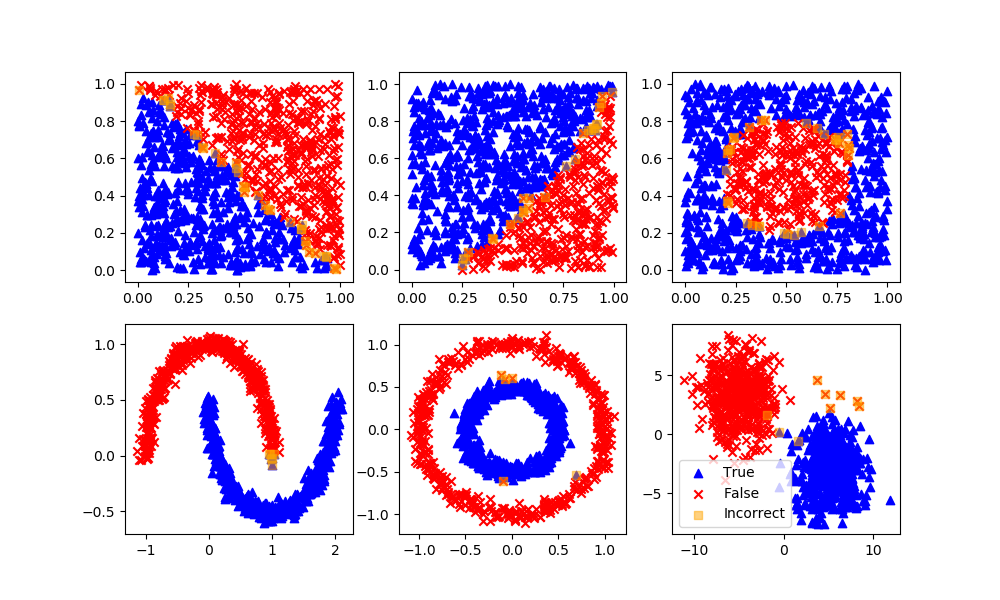

### Random Forest

**Definition:** Random forest classifier is a meta-estimator that fits a number of decision trees on various sub-samples of datasets and uses average to improve the predictive accuracy of the model and controls over-fitting. The sub-sample size is always the same as the original input sample size but the samples are drawn with replacement.

**Advantages:** Reduction in over-fitting and random forest classifier is more accurate than decision trees in most cases.

**Disadvantages:** Slow real time prediction, difficult to implement, and complex algorithm.

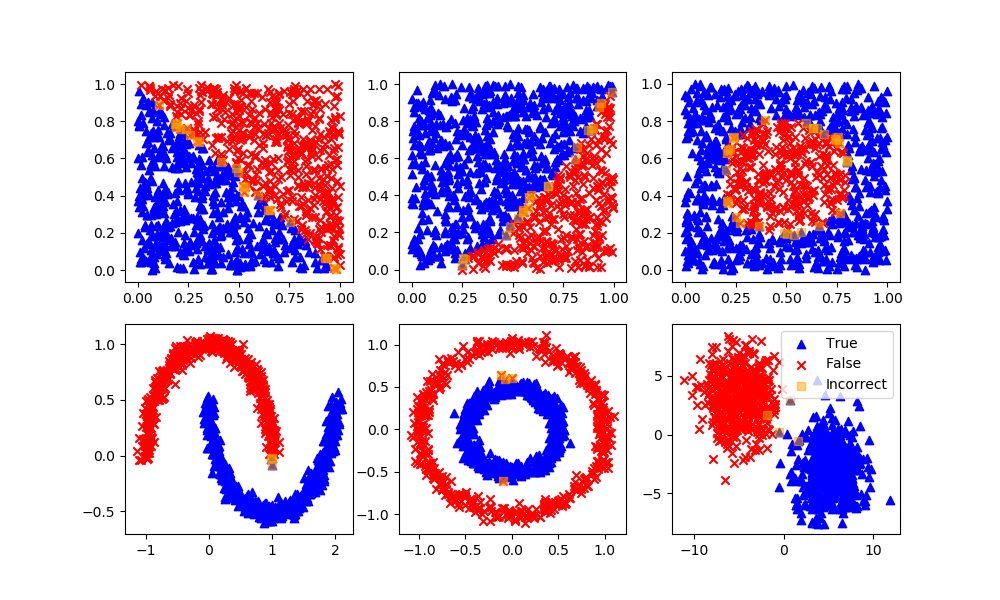

### Support Vector Classifier

**Definition:** Support vector machine is a representation of the training data as points in space separated into categories by a clear gap that is as wide as possible. New examples are then mapped into that same space and predicted to belong to a category based on which side of the gap they fall.

**Advantages:** Effective in high dimensional spaces and uses a subset of training points in the decision function so it is also memory efficient.

**Disadvantages:** The algorithm does not directly provide probability estimates, these are calculated using an expensive five-fold cross-validation.

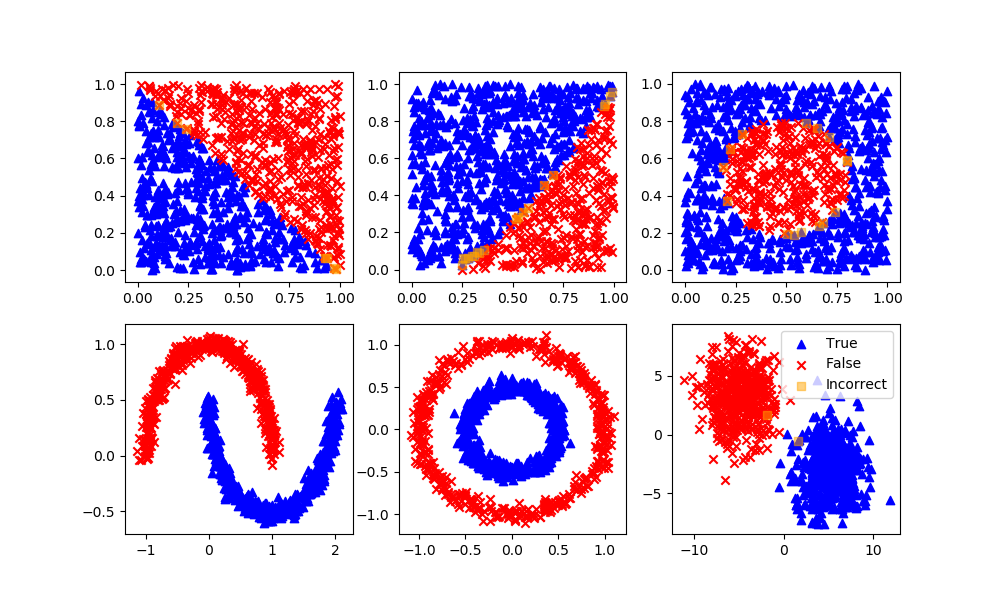

### Deep Learning Neural Network

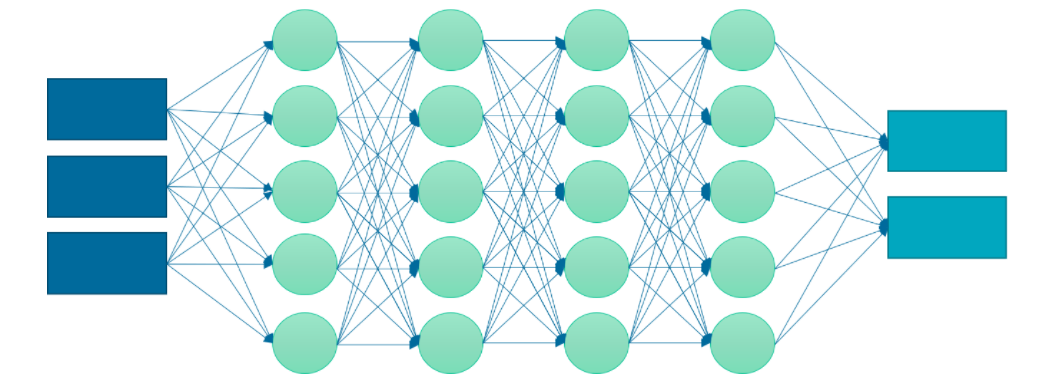

**Definition:** A neural network is a set of neurons (activation functions) in layers that are processed sequentially to relate an input to an output. This example implements a multi-layer perceptron (MLP) algorithm that trains using Backpropagation.

**Advantages:** Effective in nonlinear spaces where the structure of the relationship is not linear. No prior knowledge or specialized equation structure is defined although there are different network architectures that may lead to a better result.

**Disadvantages:** Neural networks do not extrapolate well outside of the training domain. They may also require longer to train by adjusting the parameter weights to minimize a loss (objective) function. It is also more challenging to explain the outcome of the training and changes in initialization or number of epochs (iterations) may lead to different results. Too many epochs may lead to overfitting, especially if there are excess parameters beyond the minimum needed to capture the input to output relationship.

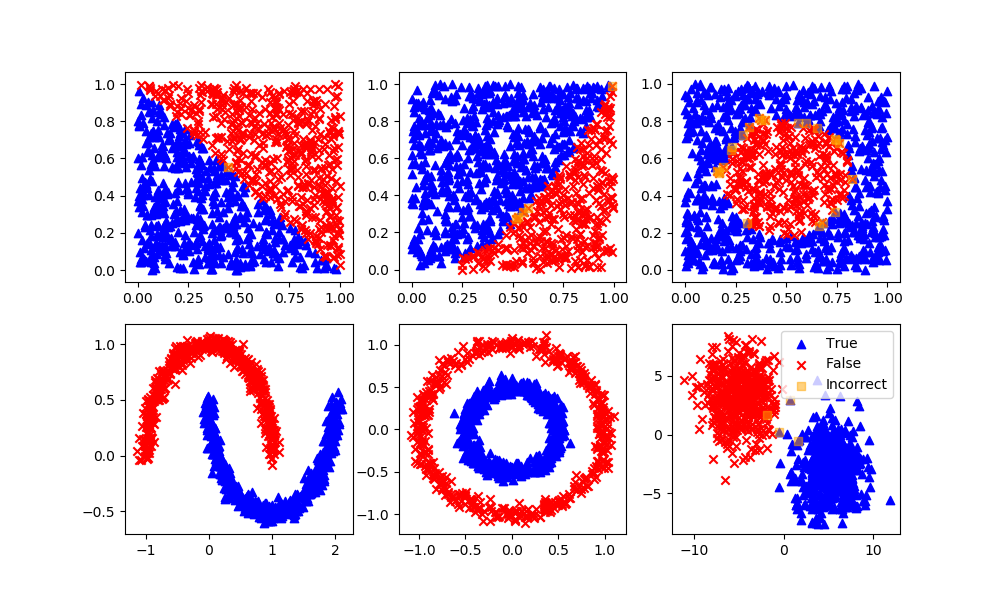

## Classification with Unsupervised Learning

### K-Means Clustering

**Definition:** Specify how many possible clusters (or K) there are in the dataset. The algorithm then iteratively moves the K-centers and selects the datapoints that are closest to that centroid in the cluster.

**Advantages:** The most common and simplest clustering algorithm.

**Disadvantages:** Must specify the number of clusters although this can typically be determined by increasing the number of clusters until the objective function does not change significantly.

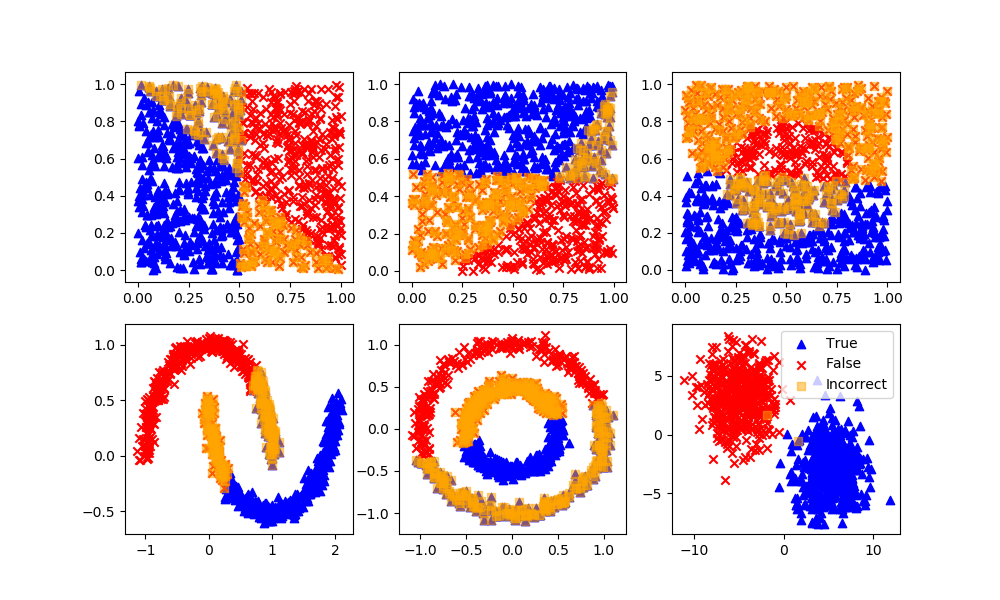

### Gaussian Mixture Model

**Definition:** Data points that exist at the boundary of clusters may simply have similar probabilities of being on either clusters. A mixture model predicts a probability instead of a hard classification such as K-Means clustering.

**Advantages:** Incorporates uncertainty into the solution.

**Disadvantages:** Uncertainty may not be desirable for some applications. This method is not as common as the K-Means method for clustering.

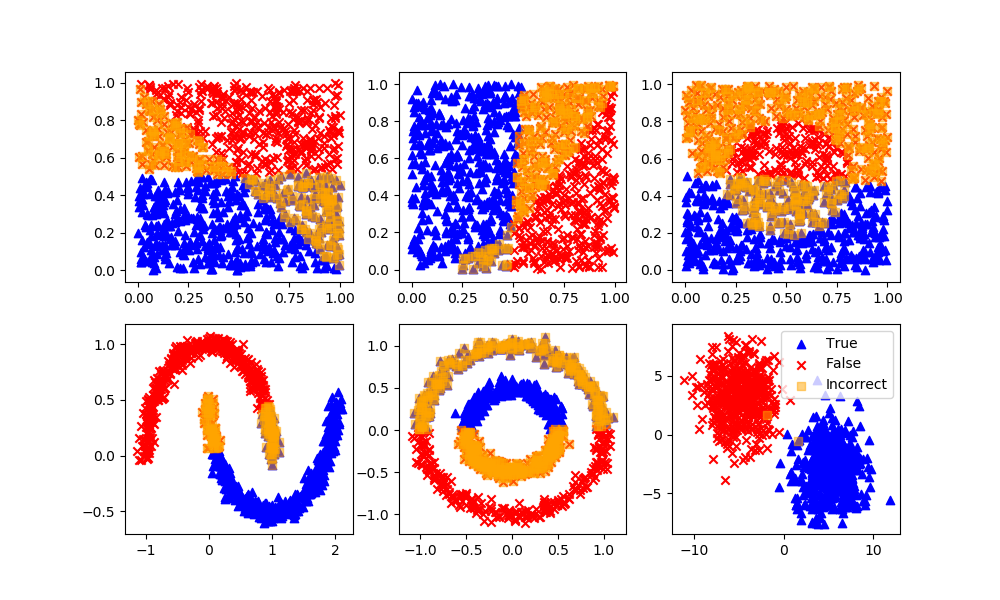

### Spectral Clustering

**Definition:** Spectral clustering is known as segmentation-based object categorization. It is a technique with roots in graph theory, where identify communities of nodes in a graph are based on the edges connecting them. The method is flexible and allows clustering of non graph data as well. It uses information from the eigenvalues of special matrices built from the graph or the data set.

**Advantages:** Flexible approach for finding clusters when data doesn’t meet the requirements of other common algorithms.

**Disadvantages:** For large-sized graphs, the second eigenvalue of the (normalized) graph Laplacian matrix is often ill-conditioned, leading to slow convergence of iterative eigenvalue solvers. Spectral clustering is computationally expensive unless the graph is sparse and the similarity matrix can be efficiently constructed.

### Summary

Classification with machine learning is through supervised (labeled outcomes), unsupervised (unlabeled outcomes), or with semi-supervised (some labeled outcomes) methods. From the many methods for classification the best one depends on the problem objectives, data characteristics, and data availability. Below is a complete compilation of the source code for supervised and unsupervised learning methods.

#### Source Code

### Exercise

Develop a classifier to predict when the [**TCLab heater**](https://apmonitor.com/heat.htm) is on and when it is off. Generate labeled data where the heater is either on at 100% output or at 0% output for periods between 10 and 25 seconds.

*Small Data Set (10 min)*

We test the classifier by splitting the data set into a training and test set. The data is generated from a TCLab or accessed at the link below.

 [**Data for Testing**](https://apmonitor.com/do/uploads/Main/tclab_data5.txt)

**Generate Small Data**

*Large Data Set (1 hr)*

 [**Data for Training**](https://apmonitor.com/do/uploads/Main/tclab_data6.txt)

**Generate Large Data**

Select and scale (0-1) the features of the data such as temperature, and temperature derivatives. Use the measured temperature and derivatives and heater value labels to create a classifier that predicts when the heater is on or off. Validate the classifier with new data that was not used for training.

**Solutions**